## RRT

% parking lot costmap generation
parking_spot = 4;
road_file_path = 'ParkingLotGeneration/ParkingLines/polylines9.shp';
parking_points_file_path = 'ParkingLotGeneration/ParkingSpots/points6.shp';
car_width  = 0.000005;
car_length = 0.00002;
road_f = shaperead(road_file_path);
points_f = shaperead(parking_points_file_path);
info = shapeinfo(road_file_path);
boundary_bounds = info.BoundingBox;
min_col = boundary_bounds(1, 1);
min_row = boundary_bounds(1, 2);
max_col = boundary_bounds(2, 1);
max_row = boundary_bounds(2, 2);
costmap = parking.generateCostMap(road_f, max_row, min_row, max_col, min_col);
% cost_map = vehicleCostmap(costmap);

Currently, this rrt algorithm does not generate equidistant path segments, if it is needed, we can modify the random method.

I'm also not using vehicleCostmap object anymore because I was having some problem with it. 

startPos = int64([0,0,0]); %x,y,theta (radians)
goalPos = [100,100,pi/4];
minTurning = 10; %in meters
iterations = 2000;
tree = rrt(costmap, iterations, startPos, goalPos, minTurning);

[path, Tree]= run(tree);

number of nodes in graph: 208.0
     1     3    10    12    21    25    38    78   207   208



%if path is empty (i.e. did not find a path in last run), run again
%will fix this later
for i = 1: length(path)
    disp(path{i});
end

   0   0   0

  314.0000  132.0000    0.3980

  184.0000  196.0000    2.6841

  203.0000  119.0000    4.9543

  180.0000   45.0000    4.4110

  139.0000   10.0000    3.8482

   92.0000   16.0000    3.0146

  108.0000   66.0000    1.2611

  101.0000  104.0000    1.7530

  100.0000  100.0000    0.7854



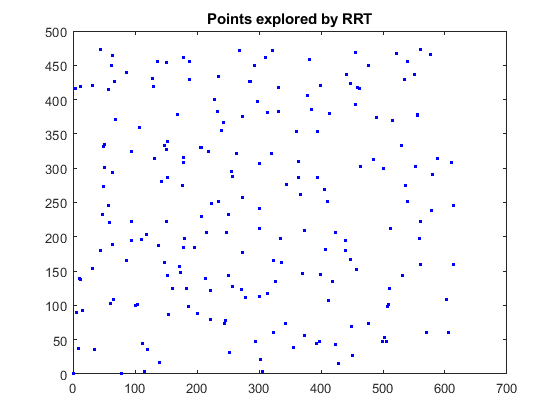

[X, Y, Theta] = convert_cell_vector_to_double_vectors(tree.nodes);
figure
plot(Y, X, 'b.')
title('Points explored by RRT')

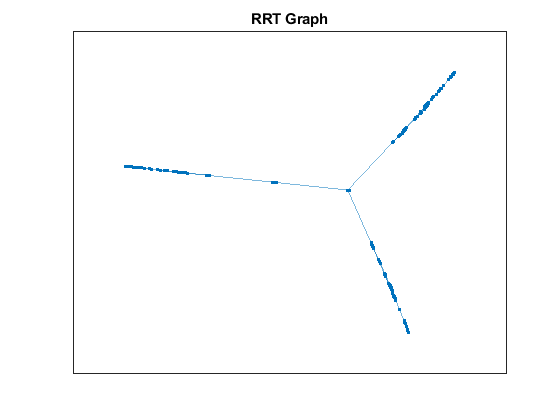

G = graph(tree.s, tree.t, tree.weight);
plot(G);
title('RRT Graph')

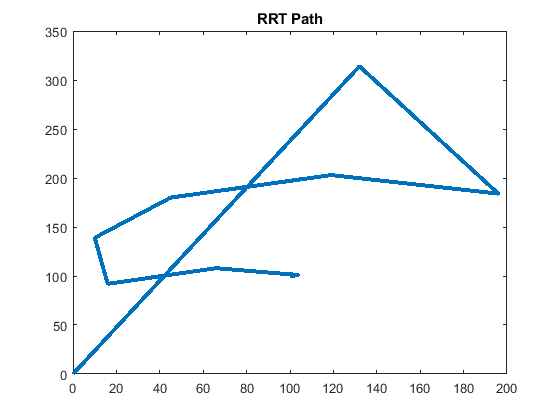

[X1, Y1, Theta1] = convert_cell_vector_to_double_vectors(path);
figure
plot(Y1, X1, 'LineWidth', 3)
title('RRT Path')

%% Processing for plotting, should we just change the data structure itself
% this way?? Open Question...

function [X, Y, Theta] = convert_cell_vector_to_double_vectors(data)
    size = length(data);
    X = zeros(size);
    Y = zeros(size);
    Theta = zeros(size);
    for i = 1:size
        n = data{i};
        X(i) = n(1);
        Y(i) = n(2);
        Theta(i) = n(3);
    end
end
%%reference link:
%https://github.com/Mayankm96/Motion-Planning-GUI/blob/master/GUI/RRTree/RRT.m
